# Homepage

## Input audio file

file = "C:\Users\matth\Documents\GitHub\sl3BatmanProject\codes\testaudio1.mp3";

## Guitar effect selection

effect = "Flanger";

## Parameters

### Distortion

gain = 6.05;    tone = 0.483;

### Digital delay

time = 0.345;   feedback = 0.93;

### Phaser

mix_p  = 0.7; delay      = 0.015;
range  = 10;  sweep_freq = 3.69;

### Flanger

depth = 0.0225;  rate = 8.56;
mix_f   = 0.55;

## Preferences

WriteNewFile = false; % Check box to write effect output as new file
PlayAudio    = false; % Check box to play audio after applying the effect
 

% Gather audio information
clear sound
info = audioinfo(file);
[audio, fs] = audioread(file);
[~, col] = size(audio);
if col == 2, audio = (audio(:, 1) + audio(:, 2))/2; end
clear col

% Save data to .mat file
save("A_Homepage.mat")
clearvars -except effect file

% Load or run guitar effects mlx
if effect == "Distortion"
    run("B_Distortion.mlx")
elseif effect == "Digital Delay"
    run("C_DigitalDelay.mlx")
elseif effect == "Phaser"
    run("D_Phaser.mlx")
elseif effect == "Flanger"
    run("E_Flanger.mlx")
end
load("effectoutput.mat")
fprintf("Done! Performed " + effect + ".")

Done! Performed Flanger.

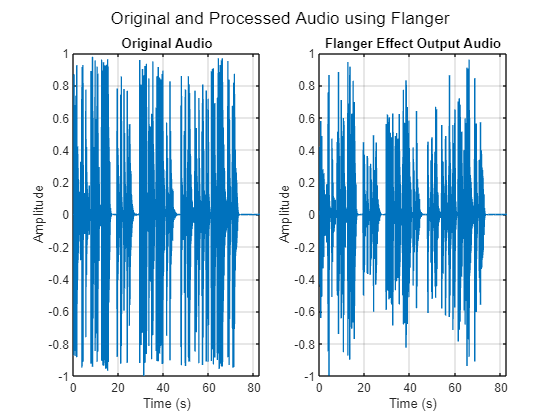


% Write effect output as new audio file
if WriteNewFile == 1
    newfile = effect + "_output.wav"
    audiowrite(newfile, output, fs)
end

% Play the effect output
if PlayAudio == 1
    clear sound
    sound(output, fs)
    fprintf("Playing audio...")
end

clearvars -except audio output fs effect

audio = audio(1 : length(output));
t = 0 : 1/fs : (length(audio)-1)/fs;
clf
figure
sgtitle("Original and Processed Audio using " + effect)
 
subplot(1, 2, 1)
plot(t, audio)
grid on
xlim([0 max(t)])
xlabel("Time (s)") 
ylabel("Amplitude")
title("Original Audio")

subplot(1, 2, 2)
plot(t, output)
grid on
xlim([0 max(t)])
xlabel("Time (s)")
ylabel("Amplitude")
title(effect + " Effect Output Audio")


return

clear sound
sound(output, fs)
 

clear sound
 